# Ex01. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1.1. Develop 8 Exponential Signals As a Graph

 This assignment involves creating eight graphs representing exponential signals. These signals are discrete-time and defined over the range of integers n from -100 to 100.  The eight graphs are generated based on combinations of three factors: whether the real or imaginary part of the complex signal is plotted, the presence of noise, and the sign of the damping factor (or real part of the complex frequency) σ.

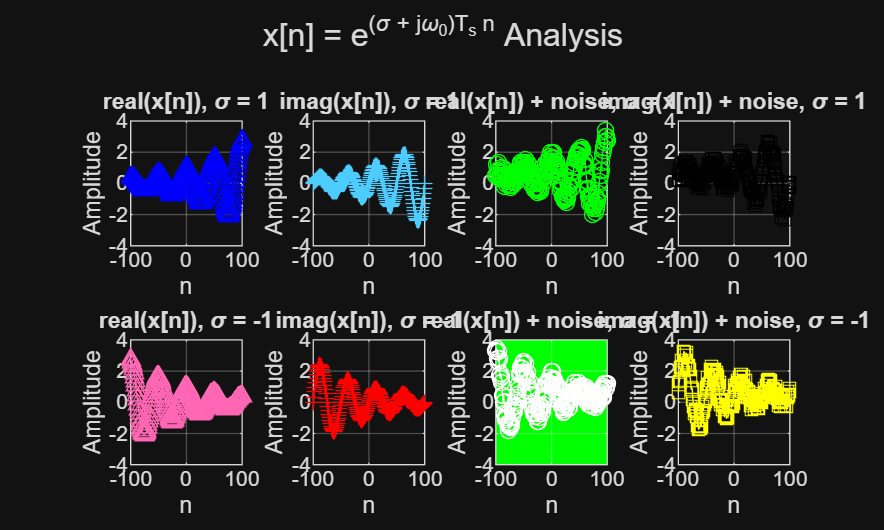

n = -100:100;
T0 = 0.5;
Ts = 0.01;
sigma_values = [+1, -1];
w0 = 2*pi/T0;

figure('Position', [100, 100, 1000, 600]);

sigma = sigma_values(1);
x = exp((sigma + j * w0)* Ts * n);

% Calculate the real and imaginary parts of the signal
realPart = real(x);
imagPart = imag(x);

% Define noise
noise = 1.0 * rand(size(x));
realPart_noise = noise + realPart;
imagPart_noise = noise + imagPart;

subplot(2,4,1);
p1 = plot(n, realPart);
title(strcat("real(x[n]), \sigma = ", num2str(sigma)));
xlabel("n");
ylabel("Amplitude");
axis([-100 100 -4 4]);
set(p1, 'Color', 'b');
set(p1, 'Marker', '^');
grid on;

subplot(2,4,2);
p2 = plot(n, imagPart);
title(strcat("imag(x[n]), \sigma = ", num2str(sigma)));
xlabel("n");
ylabel("Amplitude");
axis([-100 100 -4 4]);
set(p2, 'Color', '[0.3 0.8 1.0]');
set(p2, 'Marker', '+');
grid on;

subplot(2,4,3);
p3 = plot(n, realPart_noise);
title(strcat("real(x[n]) + noise, \sigma = ", num2str(sigma)));
xlabel("n");
ylabel("Amplitude");
axis([-100 100 -4 4]);
set(p3, 'Color', 'g');
set(p3, 'Marker', 'o');
grid on;

subplot(2,4,4);
p4 = plot(n, imagPart_noise);
title(strcat("imag(x[n]) + noise, \sigma = ", num2str(sigma)));
xlabel("n");
ylabel("Amplitude");
axis([-100 100 -4 4]);
set(p4, 'Color', 'k');
set(p4, 'Marker', 'square');
grid on;


sigma = sigma_values(2);
x = exp((sigma + j * w0)* Ts * n);

% Calculate the real and imaginary parts of the signal
realPart = real(x);
imagPart = imag(x);

% Define noise
noise = 1.0 * rand(size(x));
realPart_noise = noise + realPart;
imagPart_noise = noise + imagPart;

subplot(2,4,5);
p1 = plot(n, realPart);
title(strcat("real(x[n]), \sigma = ", num2str(sigma)));
xlabel("n");
ylabel("Amplitude");
axis([-100 100 -4 4]);
set(p1, 'Color', '[1.0 0.4 0.7]');
set(p1, 'Marker', '^');
grid on;

subplot(2,4,6);
p2 = plot(n, imagPart);
title(strcat("imag(x[n]), \sigma = ", num2str(sigma)));
xlabel("n");
ylabel("Amplitude");
axis([-100 100 -4 4]);
set(p2, 'Color', 'red');
set(p2, 'Marker', '+');
grid on;

subplot(2,4,7);
p3 = plot(n, realPart_noise);
title(strcat("real(x[n]) + noise, \sigma = ", num2str(sigma)));
xlabel("n");
ylabel("Amplitude");
axis([-100 100 -4 4]);
set(p3, 'Color', 'w');
set(p3, 'Marker', 'o');
ax = gca;
set(ax, 'Color', 'g');
grid on;

subplot(2,4,8);
p4 = plot(n, imagPart_noise);
title(strcat("imag(x[n]) + noise, \sigma = ", num2str(sigma)));
xlabel("n");
ylabel("Amplitude");
axis([-100 100 -4 4]);
set(p4, 'Color', 'yellow');
set(p4, 'Marker', 'square');
grid on;

%% Below is the 8 graph required in the assignemnt.
sgtitle('x[n] = e^{(\sigma + j\omega_0)T_s n} Analysis');

## 1.2. Math Problem

 Below is the snapshot of my answer in fill-blank math problem.